## Calcular hidroperiodo (h/mes, cm/mes, eventos/mes)

Este script ayuda a calcular las tres variables del hidroperiodo para una serie de tiempo previamente corregida. Se recomienda correr este codigo por secciones leyendo la guía que se encuentra en Github:

***https://github.com/LAACit/Hidp***

#### Abrir datos 

Abrimos la matriz de datos que fue limpiada con anterioridad. Se puede explorar la matriz y observar su estructura. 

datos=importdata("01_datos\Rs01_NivelesCorregidosCm_CURSO.mat")

**SELECCIÓN DE SITIO DE INTERÉS**

Aquí vamos a seleccionar la columna de interés **(sitio1, Sito2... etc)**

Sitio=7

Sitio = 7

Abre una nueva variable para almacenar los datos del sitio seleccionado 

df=datos(:,[1:6,Sitio]);

**Visualizamos los datos seleccionados **

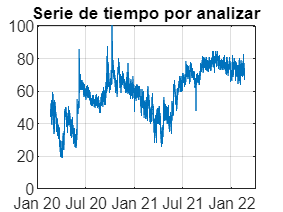

tt=datetime(df(:,1:6)); %Separamos el tiempo
figure()
plot(tt,df(:,7)) 
grid on 
yline(0)
title("Serie de tiempo por analizar")

**Creación de espacios de almacenamiento **

En estas líneas se divide la serie de tiempo en meses y se crean los espacios para almacenar las variables de hidroperiodo así como lo necesario para calcularlas. 

*No es necesario modificar estar parte del codigo *

% 2) Preparamos arreglos  vacios para llenarlos posteriormente 

% Primero se identifican el intervalo de años que tenemos
years=unique(df(:,1))

years =     20
    21
    22



% Numero de años 
nyears = length(unique(df(:, 1)));

% 3a) Se define arreglo para guardar los años 
year = cell(nyears, 1);

for i = 1:nyears
    year{i, 1} = df(:, 1) == years(i);
    year{i,2}= df(year{i,1},:); 
end
clear i 

En algunos casos las series de tiempo incluyen dos años. Por lo anterior, se necesita seleccionar un año para hacer el calculo

**SELECCIÓN DE AÑO DE INTERÉS**

yr=1

yr = 1

Aqui el scrip seleciona y muestra el año 

% 3b) Escogemos un año para sacarlos promedios mensuales
ano=year{yr,2};    %Escogemos el año modificando el valor del primer numero 
display(ano(1,1))  %muestra el año escogido 

    20



**Aqui el scrip divide la serie de tiempo de meses y almacena cada segmento en un espacio dentro de la matriz**

No es necesario modificar esta parte del codigo 

% 3c) Separamos los datos del año escogido  por mes 

mes=cell(12); %Hacemos un arreglo para guardar los resultados 
for i=1:12;                  %(Aquí 1= Enero, 2= Febrero etc) 
    mes{i,1}=ano(:,2)==i;
    mes{i,2}=ano(mes{i,1},:);
end
clear i

## **-Calculamos Hidroperiodo-**

En la siguiente sección el script calculará las tres variables del hidroperiodo y va a almacenar los resultados dentro de*** matriz mes *** que se genero en los pasos anteriores. En principio no es necesario modificar esta parte del codigo ya que hace el calculo para cada mes del año seleccionado

#### DURACIÓN Y PROMEDIO 

for i=1:12; 
    horas=0;
    for j=1:length(mes{i,2});
        if mes{i,2}(j,7)>0; %Condición para el contador, la inundación > 0 cm de agua (Inundado)
        horas=horas+1; %Contador de horas inundado 
    end
    mes{i,5}=horas;  %Almacena el Numero de horas x mes inundado: Tiempo de inundadación
    mes{i,6}=mean(mes{i,2}(:,7));%Almacena el  Nivel promedio mesual de inundación; Nivel inundación 
    end
    clear horas
end
clear i 

#### FRECUENCIA  (eventos/mes)

El calculo de la frecuencia resulta un poco más complicado por la necesidad de definir e identificar lo que es un "evento de inundación". Este script busca priorizar aquellas inundaciónes que sean significativas. Por lo anterior, la señal original es suavizada para evitar contar aquellos eventos que pueden resultar de errores en el instrumento, y define un "evento de inundación" como el  maximos locales que hay en un segmento de la serie de tiempo. Esto siguiendo la lógica de los mínimos y máximos de la derivada de una función. 

Se quitan los valores menores a 0 (que son no inundación y que pueden interferir con el conteo)


for i=1:12   
    for j=1:length(mes{i,2});
        if mes{i,2}(j,7)<=0; %Condición para el contador, la inundación > 0 cm de agua 
            mes{i,2}(j,7)=0;
        end
    end
end


**Suavizar la señal**

En este espacio se debe señalar que la función utilizada para suavizar es "movmedian", con una ventana de 8 datos. Este método fue seleccionado sobre los otros por su buen ajuste a las señales de manglar. Sin embargo, cada serie de tiempo es única y es posible que este método y/o la ventana no sean optimos para otras series de tiempo.

***EL PARAMETRO SE PUEDE MODIFICAR DE ACUERDO A LA REVISIÓN Y CRITERIO DE CADA USUARIO. ***Checar pagina de smoothdata para conocer otras opciones ;)

for i=1:12  
    for j=1:length(mes{i,2})
        mes{i,3}=smoothdata(mes{i,2}(:,7),"movmedian",8);
    end
end


Se identifican los maximos de la señal

%Ahora identificamos los maximos 
for i=1:12;   
    for j=1:length(mes{i,2});
        mes{i,4}=islocalmax(mes{i,3});
    end
end
clear i 

Se cuenta el numero de máximos por mes  **Frecuencia (eventos inundación/mes).**

for i=1:12 
    max=0;
    for j=1:length(mes{i,2})
        if mes{i,4}(j,1)==1 %Condición para el contador
        max=max+1;          %Contador de horas 
        end
        mes{i,7}=max;
    end
end
clear i j 

**Graficamos Maximos **

Para verificar el comportamiento de la función de suavizado podemos comparar la señal original y ver los eventos de inundación que se identificaron  

%asignamos un timevector
for i=1:12
    mes{i,8}=datetime(mes{i,2}(:,1:6));
end
clear i 

**Graficamos **

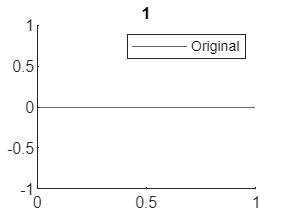

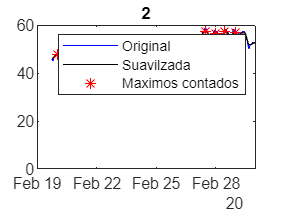

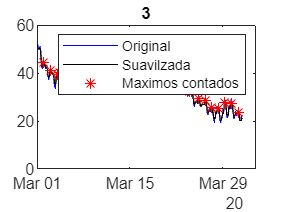

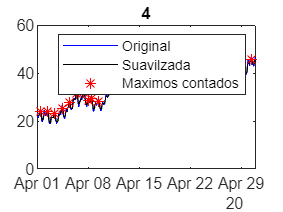

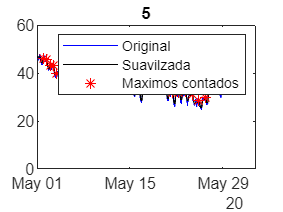

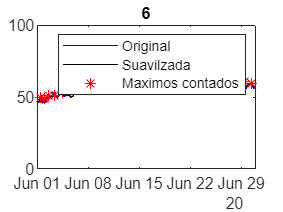

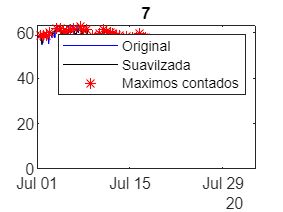

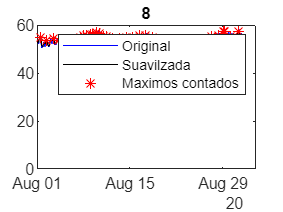

for i=1:12;    
    figure()
    plot(mes{i,8},mes{i,2}(:,7),'b')
    hold on 
    plot(mes{i,8},mes{i,3},'k')
    hold on 
    plot(mes{i,8}(mes{i,4},:),mes{i,3}(mes{i,4},:),'r*')
    yline(0)
    title(i)
    legend("Original","Suavilzada","Maximos contados")
end 

clear i

**Resultados hidroperido **

Finalmente, se muestran los resultados del calculo ordenados de la siguiente manera; 

- columna 5: Duración (h/mes)

- columna 6: Promedio (cm/mes)

- columna 7: Frecuencia (eventos/mes)

display(mes(:,5:7))

  12×3 cell array

    {0×0 double}    {0×0 double}    {0×0 double}
    {[     246]}    {[ 50.2098]}    {[      14]}
    {[     744]}    {[ 37.0616]}    {[      33]}
    {[     720]}    {[ 37.7094]}    {[      35]}
    {[     744]}    {[ 36.5011]}    {[      36]}
    {[     720]}    {[ 60.9983]}    {[      41]}
    {[     744]}    {[ 56.7866]}    {[      47]}
    {[     744]}    {[ 53.0677]}    {[      46]}
    {[     720]}    {[ 61.9104]}    {[      40]}
    {[     744]}    {[ 68.5616]}    {[      42]}
    {[     720]}    {[ 66.5726]}    {[      49]}
    {[     744]}    {[ 62.4980]}    {[      44]}



Se pueden guardar los resultados en un csv 

%writecell(mes(:,5:7),"../hp.csv")

***Calcula espectro de frecuencias (FFT)***

En esta parte se hará el calculo de las frecuencias de inundación de las series de tiempo. Para esto se tomará en consideración la serie de tiempo original. Porque así vamos a poder conocer cuales son las frecuencias dominantes en los sitios de estudio

**Preparamos los datos para el calculo de la FFT**

Frecuencia de muestreo: corresponde al numero de muestras dentro de un ciclo de interés. Este valor se debe modificar de acuerdo a la tasa de muestreo de nuestro instrumento y nuestros objetivos

Fs = 24;            % Frecuencia de muestreo  

Otros datos para construir la fft

T = 1/Fs;             % Periodo de muestreo     
L = length(datos);    % Longitud de la señal 
t = (0:L-1)*T;        % Vector de tiempo 

Se saca la fft

datosProm=detrend(datos(:,Sitio),0);
g=fft(datosProm); 

Se grafica

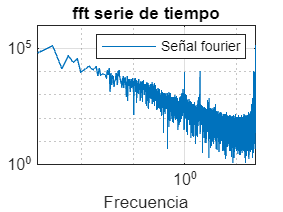

figure()
plot(Fs/L*(0:L-1),abs(g))
grid on 
xlabel("Frecuencia")
title("fft serie de tiempo completa")
legend("Señal fourier")